# Performance of Implementations of MMM with various Inner-Kernels

This Live Script helps you view the performance of implementations of MMM that, in one form or another, the three loops so that the I loop is the outer loop.  Some implementations cast computation in terms of vector-vector operations.  Some cast them in terms of matrix-vector operations.

To gather the performance data, implement and time, in the usual way,

Gemm ...

To make it easy to add to the graph incrementally as you implement these different routines, as you add new implementations, change the 'NO' to a 'YES'.  If the refence is to be plotted, then the top of the graph is also adjusted to the theoretical peak performance.  

clear all

plot_ref = 'YES';           % indicate if reference is to be plotted


plot_IJP = 'YES';          % you will want to copy output_IJP.m from
                           % Assignments/Week1/C/data/ to this directory
plot_JI_4x4Kernel = 'YES';
plot_IJP_JI_4x4Kernel = 'YES';
plot_JI_12x4Kernel = 'NO';
plot_IJP_JI_12x4Kernel = 'NO';
plot_JPI_JI_12x4Kernel = 'NO';
plot_PIJ_JI_12x4Kernel = 'NO';
plot_PI_JI_12x4Kernel = 'NO';
plot_next = 'NO';

This Life Script then creates graphs from the generated timing data.

## Load data, check accuracy, and plot timing data

turbo_clock_rate = 2.6;
flops_per_cycle = 16;
peak_gflops = 2.6 * 16;

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

if strcmp( plot_IJP, 'YES' )
    % Load data for IJP
    output_IJP
    
    if strcmp( plot_ref, 'YES' )
        % Plot time data for reference 
        plot( data(:,1), data(:,3), ...
              'MarkerSize', 8, 'LineWidth', 2, ...
              'DisplayName', 'reference', 'Color', [0 0 0] );
    end
      
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JPI                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_JI_4x4Kernel, 'YES' )
    % Load data for next
    output_JI_4x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JI_4x4Kernel        
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0.9290 0.6940 0.1250] );
end

It appears all is fine



if strcmp( plot_IJP_JI_4x4Kernel , 'YES' )
    % Load data for IJP_JI_4x4Kernel
    output_IJP_JI_4x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJP_JI_4x4Kernel           
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0.4940 0.1840 0.5560] );
end

It appears all is fine


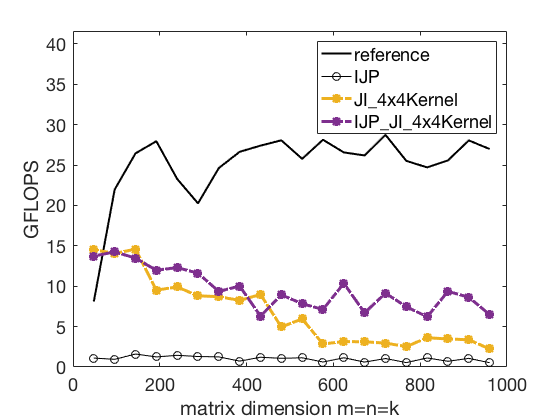


if strcmp( plot_JI_12x4Kernel, 'YES' )
    % Load data for JI_12x4Kernel
    output_JI_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JI_12x4Kernel            
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0.4660 0.6740 0.1880] );
end

if strcmp( plot_IJP_JI_12x4Kernel, 'YES' )
    % Load data for IJP_JI_12x4Kernel
    output_IJP_JI_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJP_JI_12x4Kernel           
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0.75 0.75 0] );
end

if strcmp( plot_JPI_JI_12x4Kernel, 'YES' )
    % Load data for JPI_JI_12x4Kernel
    output_JPI_JI_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JPI_JI_12x4Kernel         
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0.75 0 0.75] );
end

if strcmp( plot_PIJ_JI_12x4Kernel, 'YES' )
    % Load data for PIJ_JI_12x4Kernel
    output_PIJ_JI_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PIJ_JI_12x4Kernel             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 0.4470 0.7410] );
end


if strcmp( plot_PI_JI_12x4Kernel, 'YES' )
    % Load data for next
    output_PI_JI_12x4Kernel
    
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PI_JI_12x4Kernel             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-', 'Color', [0.8500 0.3250 0.0980] );
end



% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeast','FontSize',18);

if strcmp( plot_ref, 'YES' )
    % Adjust the x-axis and y-axis range to start at 0 and top of graph is peak
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
else
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
end